# AOI_Lab :Text Detection

### Fred liu 2023.07.11

**Basic Usage**

img = imread("txt_Image\t001.jpg");

bboxes = detectTextCRAFT(img)

bboxes =          212        3330         108          30
         234        3236         278          78
         322        3322         190          36
         336        1476          94          90
         454        1474         388          82
         482        1602         166          94
         514        3246         234          62
         524        3324          90          32
         628        3320          58          32
         672        1592         282         100


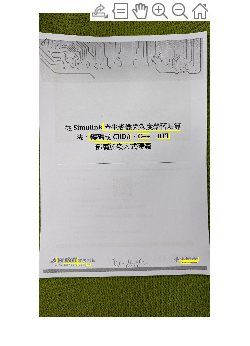

Iout = insertShape(img,"rectangle",bboxes,LineWidth=5);
figure,imshow(Iout)

**Detect Texts in ROI by using CRAFT**

指定範圍內的文字辨識(使用Doc的例子)

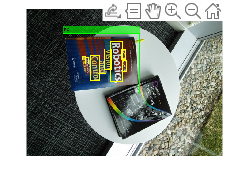

visiondatadir = fullfile(toolboxdir('vision'),'visiondata'); 
I = imread(fullfile(visiondatadir,'imageSets','books','pairOfBooks.jpg'));

roi = [120,80,250,200];
bboxes = detectTextCRAFT(I,roi);

I = insertObjectAnnotation(I,"rectangle",roi,"ROI",Color="green");
Iout = insertShape(I,"rectangle",bboxes,LineWidth=3);
figure
imshow(Iout)

**Detect Characters by Modifying Affinity Threshold**

調整參數，根據不同的LinkThreshold，展示不同的文字框切割效果

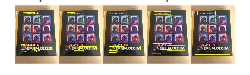

visiondatadir = fullfile(toolboxdir('vision'),'visiondata'); 
I = imread(fullfile(visiondatadir,'bookCovers','book27.jpg'));

threshold = [1 0.1 0.01 0.001 0.0004];

Iout = zeros(size(I,1),size(I,2),size(I,3),length(threshold));

for cnt = 1:length(threshold)
    bboxes = detectTextCRAFT(I,LinkThreshold=threshold(cnt));
    Iout(:,:,:,cnt) = insertShape(I,"rectangle",bboxes,LineWidth=3);
end

figure
montage(uint8(Iout),Size=[1 5],BackgroundColor="white");
title(['LinkThreshold = ' num2str(threshold(1)) ' | LinkThreshold = ' num2str(threshold(2)) ' | LinkThreshold = ' num2str(threshold(3)) ...
    ' | LinkThreshold = ' num2str(threshold(4)) ' | LinkThreshold = ' num2str(threshold(5))]);

### `Acceleration Mode`

`在LiveEditor中使用此功能有可能會失敗，建議在Command Window或是在script`

img = imread("txt_Image\t002.jpg");

bboxes = detectTextCRAFT(img,'Acceleration','mex')

Error using dlnetwork/predict
Execution failed during layer(s) 'Input_input'.

Error in detectTextCRAFT (line 36)
networkOutput = predict(craftNet,Ipreprocessed,'Acceleration',params.Acceleration);

Caused by:
    Error using nnet.internal.cnn.coder.MexNetwork/predict
    An exception occurred during the call of the MEX function.
        Error during execution of the generated code. 

Iout = insertShape(img,"rectangle",bboxes,LineWidth=5);
figure,imshow(Iout)

## `detectTextCRAFT Input Arguments`

`CharacterThreshold`** — Region threshold for characters**

CharacterThreshold = 0.4 (default)

`LinkThreshold`** — Link threshold**

LinkThreshold = 0.4 (default)

`MinSize`** — Size of smallest detectable text region**

MnSize = [6,6] (default)

`MaxSize`** — Size of largest detectable text region**

MnSize = size of input image (default)

`ExecutionEnvironment`** — Hardware resource**

`ExecutionEnvironment = "auto"` (default)

 "auto" |  "gpu" |  "cpu"

`Acceleration`** — Performance optimization**

Acceleration = "`auto"` (default)

"auto"  |  "mex"  | "none" 